# Final Project Writeup

## Behavioral: Curvature Metric

Behavioral: Find a curvature metric (ratio of actual path length to straight line distance between start and end). Plot the distribution of curvature with a bootstrapped confidence interval for curved and straight path conditions. This would be a behavioral verification that the animal actually did the curved paths and not just the straight length ones. 

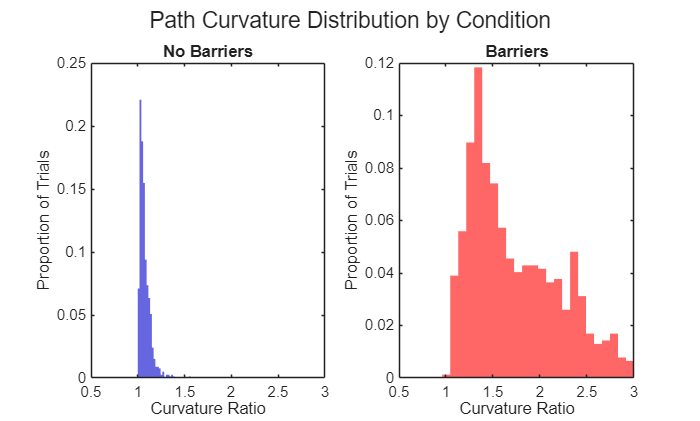

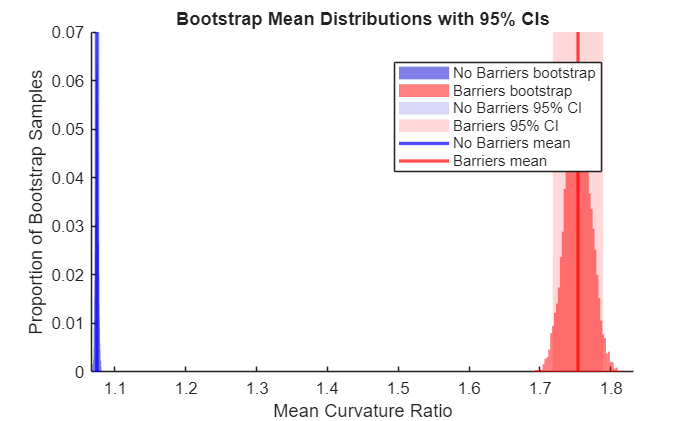

curvatureMetric(R)

The two curvature distributions are distinguishable by the barrier and no barrier conditions. In the barriers condition, we see higher variability. This is expected as the animal needed to take an actual longer path length to complete those trials. The bootstrapped confidence interval further confirms that the curved trials were accurately performed. This non overlapping confidence intervals show us that the dfference between the conditions is consistent across the population. Although we can see from the kinematic trajectory plot earlier the directions the animals took curved reaches, bootstrapping confirms that this behavior is consistent across the population of trials. 

## Behavioral: Peak Hand Velocity

Behavioral: Hand velocity over time split by the curved and straight reaches. Compute peak hand speed during trial, split trials into groups based on curved or straight reaches, compare the means. 

Monte Carlo: shuffle the curved/straight labels, recompute the difference in the means, do this 1,000 times to create a null distribution. P-value would show us if curved and straight reaches have significantly different peak hand speeds. 

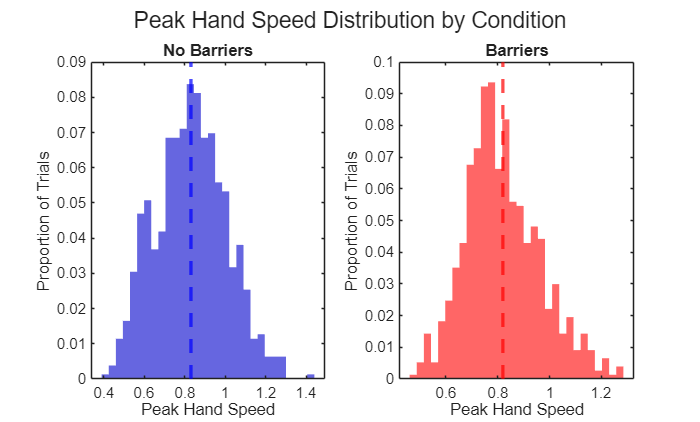

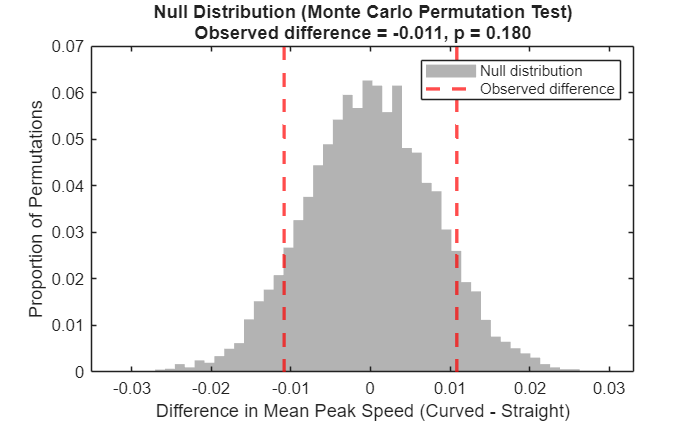

handVelocityMonteCarlo(R)

Between the barrier and no barrier conditions, the peak hand speed distributions overlap significantly. This suggests that the trajectory tasks were performed at the same speeds, reducing the confound that any variability we see in the neural data between the two conditions is due to a difference in velocity. The differences we will see in our later analyses that separate barrier and no barrier conditions will not be due to the animal maybe moving faster in or slower in one condition type. From the Monte Carlo Permutation test, we can see that our p-value is 0.180. This means that we fail to reject the null hypothesis that the no barriers and the barriers condition differ in peak sepeed. 

## Trial by Trial Variability

We will compute the Fano Factor as a function of time aligned to both the target appearance, movement onset, and go-cue separately for curved and straight reaches to determine how variability evolves across delay and movement and whether this differs for the reach types, considering curved reaches are arguably more complex.

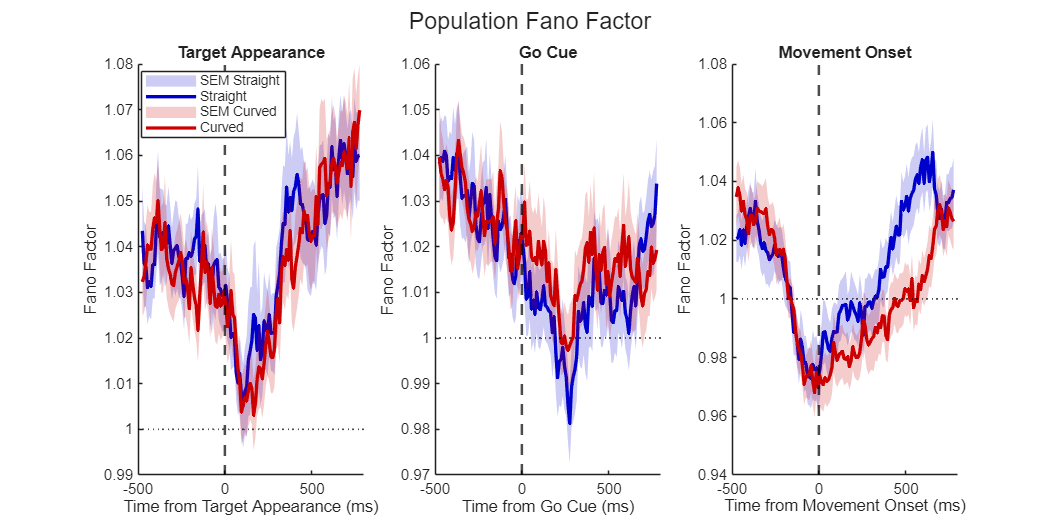

trialToTrialVariability(R)

As we learned in class, the Fano Factor (FF) is used to quantify neural variability, with FF=1 indicating regular firing. The plot shown was averaged At target appearance, the variabilty drops, and steadily rises. The same pattern is shown in the go cue alignment plot. When aligned to the movement onset, we see the straight reaches have a higher variability after movement onset compared to the curved reaches. This could mean that at movement onset, the curved trajectories execute movement in a stereotyped way. These results suggest that straight reaches are more locked to instruction, and curved reaches are more locked to execution. However, it is important to note that these differences in variability are minor. In addition, averaging over the population might minimize the differences in variability we see between the two conditions. 

## NOTE: Put in FF between arrays and single units

## Linear Dimensionality Reduction

We will do cross-validated PCA on M1 activity to determine the true low dimensional structure of the neuron's responses, comparing dimensionality under no normalization, z-scoring, and soft normalization.

Firing rates created.


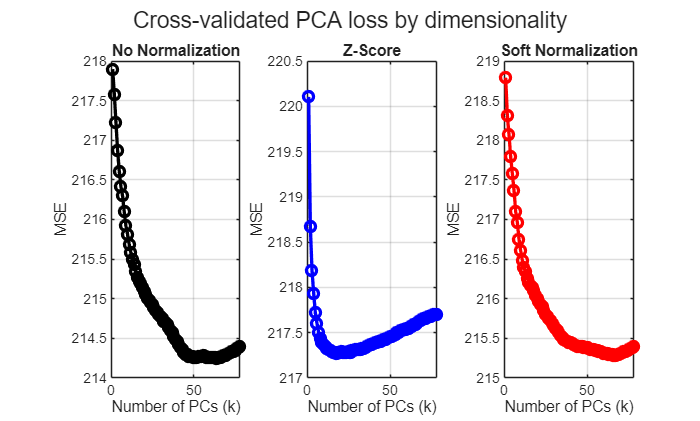

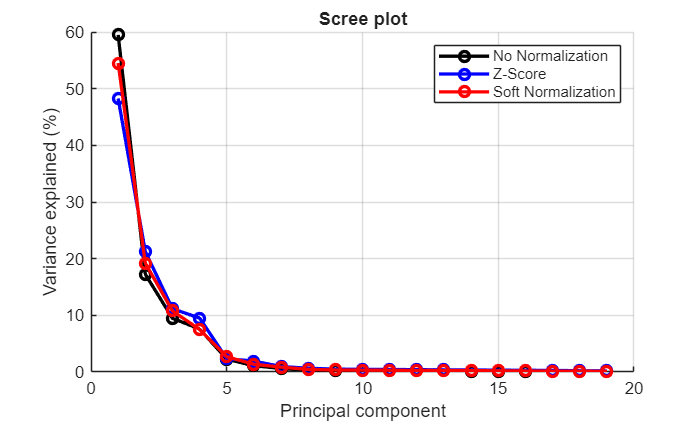

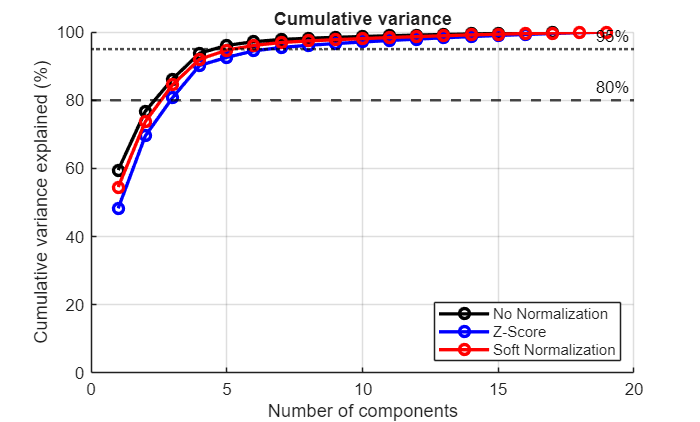

results = linearDimensionalityReduction(R);

The cross-validated PCA plots comparing MSE against the number of PCs show a U-shaped curve between the different normalizations. The sharpest U-shape is in the z-scored plot. As we learned in class, this shape is expected as we increase the number of PCs and the model begins to overfit to the noise. The optimal dimensionality is therefore at the minimum of each of these plots and is around 10 components for the Z-scored plot. This optimal dimensionality varies between the different normalizations with the no normalization and soft normalization having an optimal dimensionality closer to 40 components. In our scree plot, we can see that the first few PCs account for a disproportionate amount of the variance, which is to be expected. The cumulative variance plot also confirms this as the first few components account for the majority of the variance explained. 

## PCA Trajectory Plot

Firing rates created.


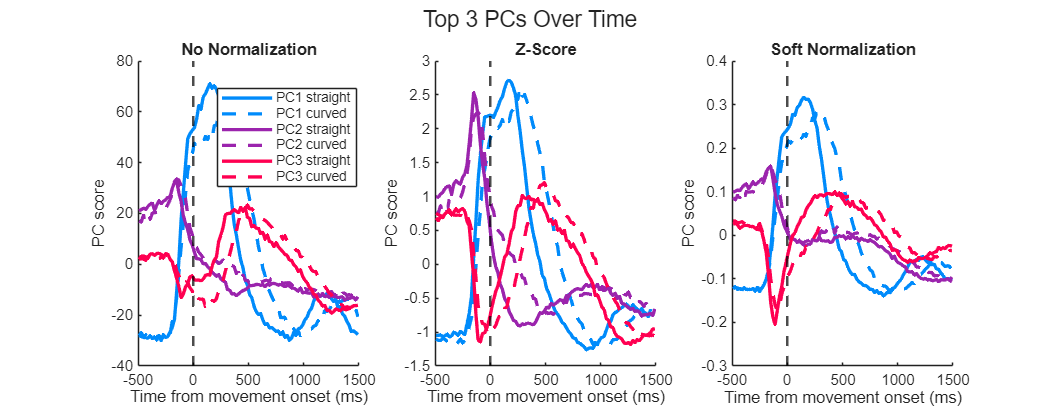

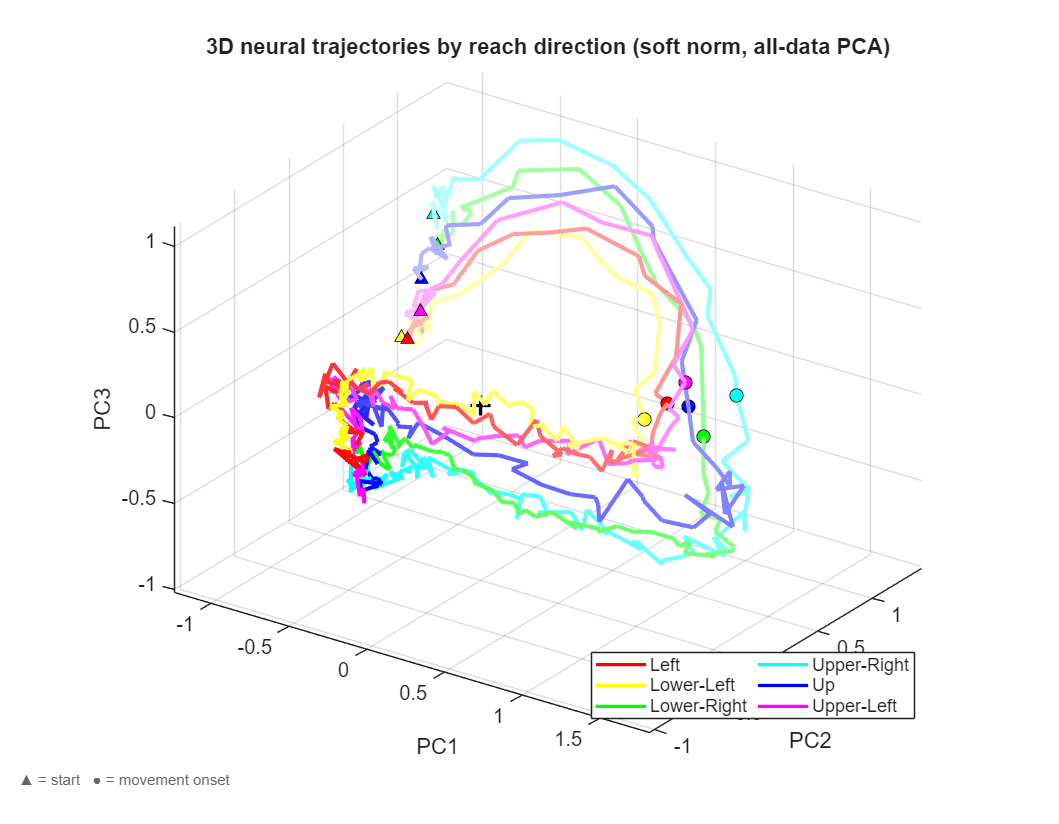

pcaTrajectories(R)

In all of these PCA trajectories, we noticed that PC1 appears to peak at movement onset. Therefore, we believe that PC1 is representative of the actual movement execution that the animal does. This peak is preserved regardless of the normalization. Based on the feedback in class, we cannot say for sure what PC2 and PC3 encode for in movement phase. We also noticed that the curved trajectories show a slight lag when compared to the straight trajectories. This might be because the curved trajectories are more complex and require more online error correction during movement execution than the straight trajectories. 

When we plot the first three PCs per time in neural space, we see that for each direction the PCs follow similar trajectories. The difference seems to be in initiation point depending on what direction condition we are looking at. This suggests that there is a condition invariant signal involved in motor preparation and execution. The structure of this plot suggests that the movement direction may set an initiation point for the rest of the dynamical system to play out during the movement period. 

## Classifer

We will classify curved vs. straight reaches based on neural data from the delay and movement period separately using SVM and logistic regression to assess when kinematic information is encoded in M1. We will assess the significance of our classifier using a Monte Carlo  shuffle test, where we shuffle curved vs straight trial labels 1000 times to generate a null distribution and compute a p-value for each method/time-window combination.

Firing rates computed.

Straight (No Barriers):
  Value    Count   Percent
      1      104     13.20%
      2      133     16.88%
      3      221     28.05%
      4      152     19.29%
      5       83     10.53%
      6       95     12.06%

Curved (Barriers):
  Value    Count   Percent
      1      109     14.17%
      2      119     15.47%
      3      219     28.48%
      4      146     18.99%
      5       85     11.05%
      6       91     11.83%

SVM (RBF) | Delay Period | Straight (No Barriers)
Observed accuracy = 0.942
p-value = 0.0010

Logistic Regression | Delay Period | Straight (No Barriers)
Observed accuracy = 0.939
p-value = 0.0010

SVM (RBF) | Movement Period | Straight (No Barriers)
Observed accuracy = 0.980
p-value = 0.0010



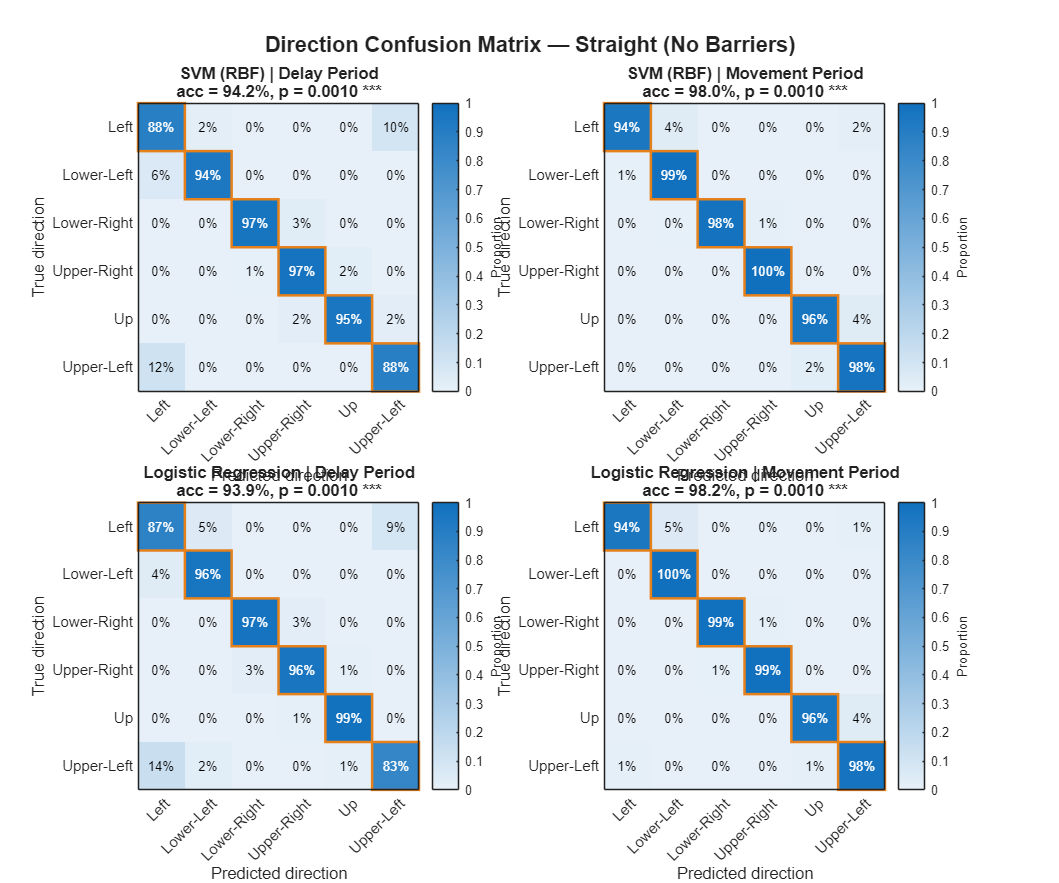

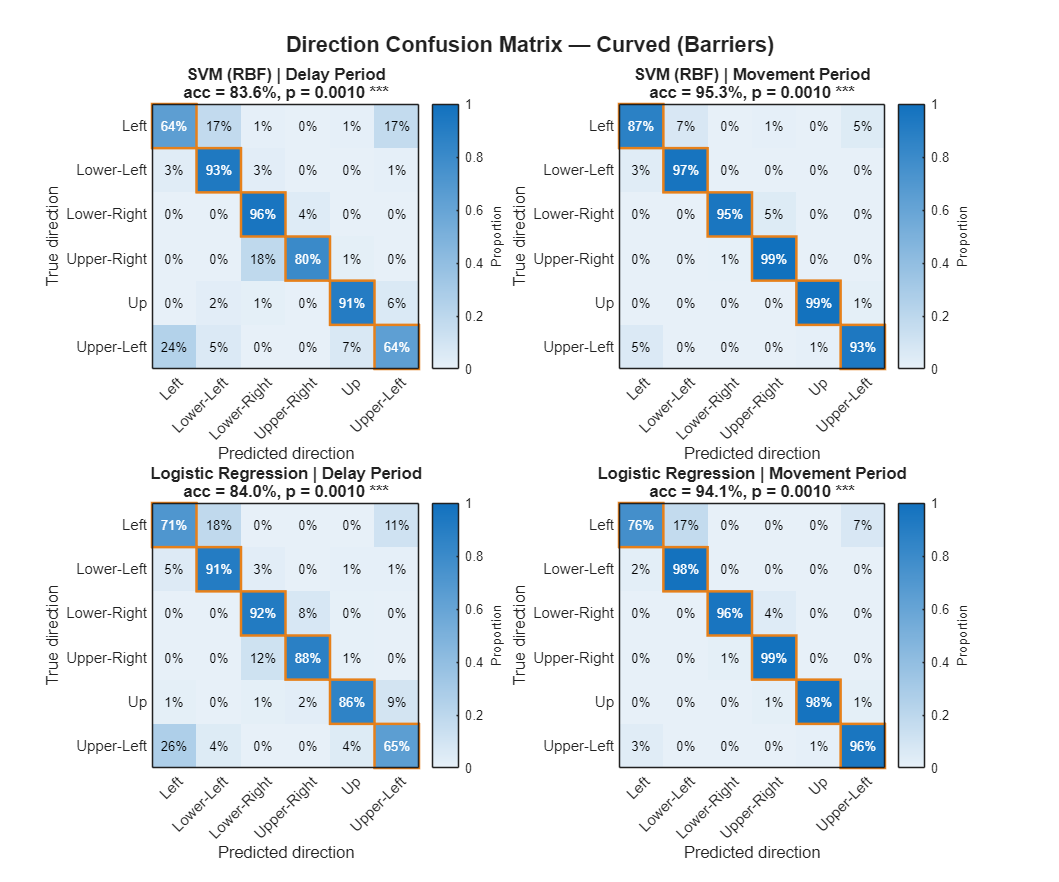

ans = struct with fields:
     obs_acc: [2×2×2 double]
    perm_acc: [2×2×2×1000 double]
    p_values: [2×2×2 double]
        pred: {2×2×2 cell}
    true_lab: {2×2×2 cell}
      params: [1×1 struct]


classifier(R)

In both the curved and straight trajectories, the classifiers performed better when trained on the movement period than on the delay period. This suggests that neural activity in the movement period more richly encodes directional information than in the delay period. In addition, both the SVM classifer with an RBF kernel and the logisitc regression performed well. This might suggest that the directions are linearly separable in neural space, as both a linear and nonlinear classifier could successfully decode direction. Also, between the curved and straight trajectories, the classifier performed well. This suggests that even though the curved trajectory might have been a more complex behavior, direction is still separable. 